clear; clc; close all;

%% Global config
sr          = 16000;        % sampling rate
clipLenSec  = 0.5;          % Each sample is 0.5 second long.
nMels       = 40;
hopLength   = round(0.01*sr);   % 10 ms
batchSize   = 64;
maxPerClass = 800;          % A maximum of 800 entries can be selected from each category.
valRatio    = 0.15;
testRatio   = 0.3;
numEpochs   = 40;
lr          = 1e-3;

dataDirSpeech   = fullfile(pwd,'speech/');
dataDirNoSpeech = fullfile(pwd,'nospeech/');

%% 1. Loading & Building VAD Datasets
fprintf('Loading dataset and extracting PCEN features...\n');

Loading dataset and extracting PCEN features...



[features, labels] = loadVADDataset( ...
    dataDirSpeech, dataDirNoSpeech, ...
    sr, clipLenSec, nMels, hopLength, maxPerClass);

Speech files: 800, Nospeech files: 800



% features:  H x W x 1 x N （H=nMels, W=time frames）
% labels:    N x 1  (0=no-speech, 1=speech)

numSamples = numel(labels);
idx = randperm(numSamples);
features = features(:,:,:,idx);
labels   = labels(idx);

%% 2. Train / Val / Test
nTest = round(testRatio * numSamples);
nVal  = round(valRatio  * numSamples);
nTrain = numSamples - nVal - nTest;

trainIdx = 1:nTrain;
valIdx   = nTrain+1 : nTrain+nVal;
testIdx  = nTrain+nVal+1 : numSamples;

XTrain = features(:,:,:,trainIdx);
YTrain = categorical(labels(trainIdx), [0 1], {'nospeech','speech'});

XVal   = features(:,:,:,valIdx);
YVal   = categorical(labels(valIdx), [0 1], {'nospeech','speech'});

XTest  = features(:,:,:,testIdx);
YTest  = categorical(labels(testIdx), [0 1], {'nospeech','speech'});

fprintf('Train: %d, Val: %d, Test: %d\n', numel(YTrain), numel(YVal), numel(YTest));

Train: 880, Val: 240, Test: 480


%% 3. Building a DS-CNN model
inputSize = size(XTrain,[1 2 3]);   % [nMels, T, 1]
numClasses = 2;

layers = buildDSCNN(inputSize, numClasses);

miniBatchSize = batchSize;
valFreq = floor(numel(YTrain)/miniBatchSize);

options = trainingOptions('adam', ...
    'InitialLearnRate', lr, ...
    'MaxEpochs', numEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',true, ...
    'ValidationData',{XVal, YVal}, ...
    'ValidationFrequency', valFreq, ...
    'ExecutionEnvironment','auto');

%% 4. Train
fprintf('Training DS-CNN model...\n');

Training DS-CNN model...


在单 GPU 上训练。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０１　｜　　　５１．５６％　｜　　４５．４２％　｜　　０．７０５０　｜　０．６７０２　｜　　０．００１０　｜
｜　　　１　｜　　　１３　｜　　　　　００：００：０１　｜　　　７５．００％　｜　　８４．１７％　｜　　０．５４０６　｜　０．５３０７　｜　　０．００１０　｜
｜　　　２　｜　　　２６　｜　　　　　００：００：０１　｜　　　７９．６９％　｜　　８７．９２％　｜　　０．４２０８　｜　０．４３４９　｜　　０．００１０　｜
｜　　　３　｜　　　３９　｜　　　　　００：００：０２　｜　　　８７．５０％　｜　　９３．７５％　｜　　０．３４１９　｜　０．３１２１　｜　　０．００１０　｜
｜　　　４　｜　　　５０　｜　　　　　００：００：０２　｜　　　７９．６９％　｜　　　　　　　　　｜　　０．３７４４　｜　　　　　　　　｜　　０．００１０　｜
｜　　　４　｜　　　５２　｜　　　　　００：００：０２　｜　　　９３．７５％　｜　　８７．９２％　｜　　０．２５３２　｜　０．３００５　｜　　０．００１０　｜
｜　　　５　｜　　　６５　｜　　　　　００：００：０２　｜　　　８４．３８％　｜　　８７．５０％　｜　　０．３１９４　｜　０．２９０７　｜　　０．００１０　｜
｜　　　６　｜　　　７８　｜　　　　　００：００：０２　｜　　　８４．３８％　｜　　９２．９２％　｜　　０．２６８７　｜　０．２１７７　｜　　０．００１０　｜
｜　　　７　｜　　　９１　｜　　　　　００：００：０２　

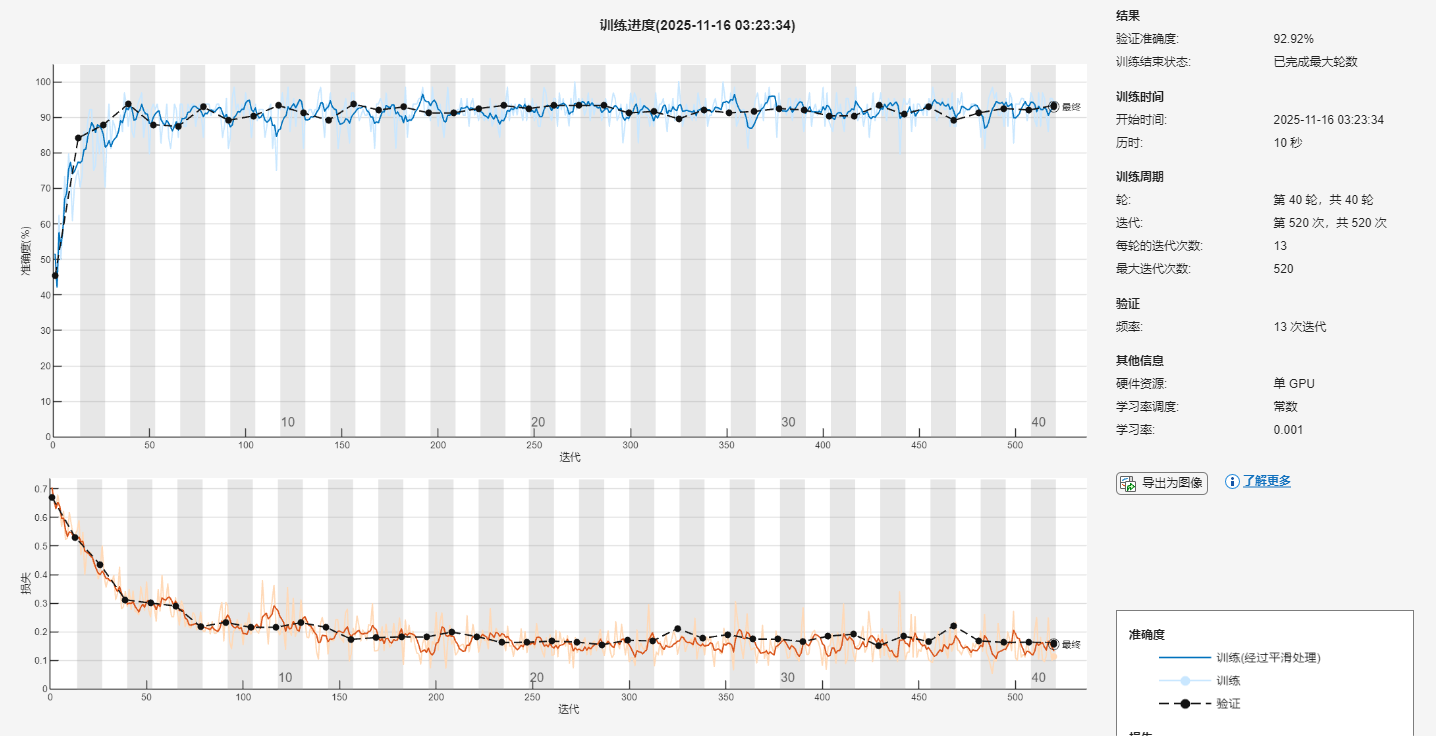

net = trainNetwork(XTrain, YTrain, layers, options);

%% 5. Evaluate on the test set
fprintf('Evaluating on test set...\n');

Evaluating on test set...


[YPred, scores] = classify(net, XTest);
[acc, precision, recall, f1, cm] = computeMetrics(YTest, YPred);

disp('DS-CNN VAD Test Performance');

DS-CNN VAD Test Performance


fprintf('Accuracy : %.4f\n', acc);

Accuracy : 0.8875


fprintf('Precision: %.4f\n', precision);

Precision: 0.8233


fprintf('Recall   : %.4f\n', recall);

Recall   : 0.9831


fprintf('F1-score : %.4f\n', f1);

F1-score : 0.8962


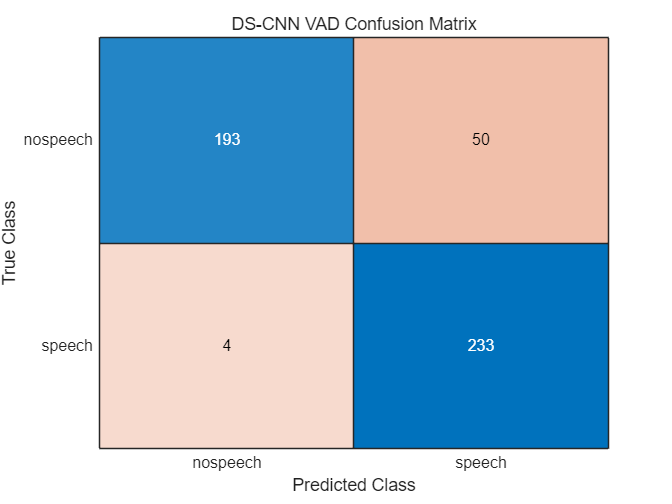


figure;
confusionchart(YTest, YPred);
xlabel("Predicted Class");
ylabel("True Class");
title('DS-CNN VAD Confusion Matrix');

%% 6. Simple baseline: Energy threshold VAD (from the same batch of test samples)
fprintf('Evaluating simple energy-based baseline...\n');

Evaluating simple energy-based baseline...


[baselinePred] = baseline_energy_vad( ...
    dataDirSpeech, dataDirNoSpeech, ...
    sr, clipLenSec, testIdx, idx, maxPerClass);

YTestNum = double(YTest=='speech');  % 1 or 0
baselinePredCat = categorical(baselinePred, [0 1], {'nospeech','speech'});

[accB, precB, recB, f1B, cmB] = computeMetrics( ...
    categorical(YTestNum,[0 1],{'nospeech','speech'}), baselinePredCat);

disp('Energy-based Baseline Test Performance');

Energy-based Baseline Test Performance


fprintf('Accuracy : %.4f\n', accB);

Accuracy : 0.4688


fprintf('Precision: %.4f\n', precB);

Precision: 0.4795


fprintf('Recall   : %.4f\n', recB);

Recall   : 0.8861


fprintf('F1-score : %.4f\n', f1B);

F1-score : 0.6222


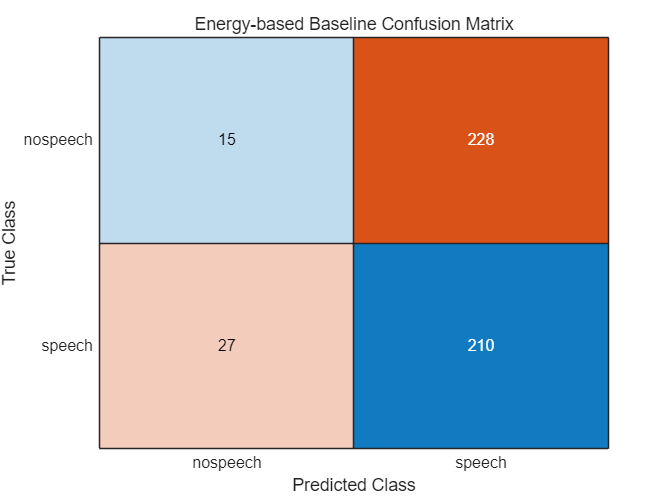

figure;
confusionchart(categorical(YTestNum,[0 1],{'nospeech','speech'}), baselinePredCat);
xlabel("Predicted Class");
ylabel("True Class");
title('Energy-based Baseline Confusion Matrix'); 